# `Ex004 - Showcase of the available PES background curves that can be used for fitting`

This example shows all of the background line-shapes that are available to use when fitting to either ARPES or PES data.

- **For Backgrounds:** **Linear**, **Shirley, ** **Offset Shirley** and **Fermi-Dirac Step **functions are all currently available.

close all; clear all;
pp = plot_props();

# **The function used to extract the best-fit background to PES data**

% First create an artificial PES spectrum, whose background will be determined
% (A) - Defining the input parameters
TYPE = "sGLA"; BE = -17.0; INT = 1.0; FWHM = 0.1; MR = 0.5; LSE = -1.0; LSI = 0.5; LSW = 0.0; ASY = 0.2;
% (B) - Calculating the lineshape
xdat_01     = linspace(BE-4, BE+4, 1e3);
ydat_01     = PESCurve(xdat_01, TYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY);
% (C) - Add artificial background and noise
ydat_01     = ydat_01 - 0.01.*xdat_01' + 0.1;
ydat_01     = ydat_01 .* (1 + 0.10*rand(length(ydat_01), 1));
% (D) - The function 'PESBackground()' can be used to fit any background line-shape profile by defining the correct arguments to the function.
help PESBackground;

  [roi_xdat, roi_ydat, roi_bgrnd] = PESBackground(xdat, ydat, bTYPE, LHS, RHS, BGR, ARGS, WIN, plot_result)
    Function that evaluates the background associated with 1D data or
    photoelectron spectroscopy (PES) data acquired at the ADRESS beamline, 
    SLS. The background type can be defined over a given region of interest
    (ROI). 
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES).
    -   ydat:           N×1 column vector of the intensity range (intensity for PES).
    -   bTYPE:          string of the type of background to use for fitting. {Default: "Poly" ("none", "Poly", "Shir", "LinShir", "StepFDDGpL", "StepFDDGsL")}
    -   LHS:            scalar of the LHS x-axis START position of the ROI. {Default: 25th percentile.}
    -   RHS:            scalar of the RHS x-axis END position of the ROI. {Default: 75th percentile.}
    -   BGR:            scalar for a constant y-axis background t

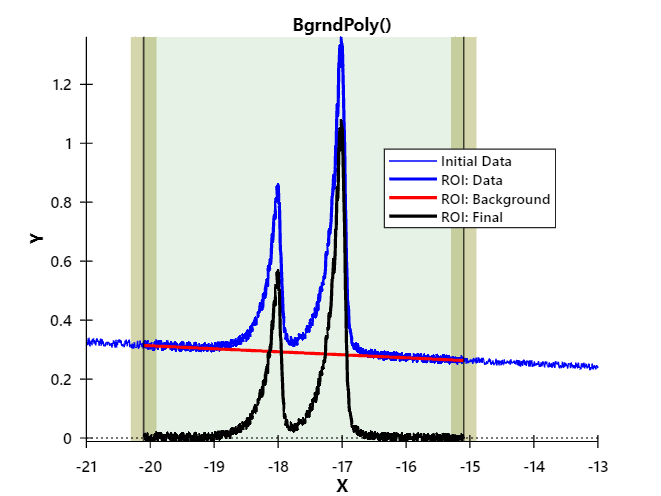

% (E) - Defining the input parameters
bTYPE   = "Poly";       % string of the type of background to use for fitting.
LHS     = -20.1;        % scalar of the START point on the LHS for background.
RHS     = -15.1;        % scalar of the END point on the RHS for background.
BGR     = 0.00;         % scalar for a constant background to be included in the fit
ARGS    = {1};          % arguments for the bTYPE
WIN     = 0.2;         % scalar for a constant background to be included in the fit
% 2 - Determination of the background the lineshape
[roi_xdat_01, roi_ydat_01, roi_bgrnd_01] = PESBackground(xdat_01, ydat_01, bTYPE, LHS, RHS, BGR, ARGS, WIN, 1);

# **Core-level background determination**

% Defining the window over which to determine the background
lhsVal      = BE-2.5;           % scalar of the LHS x-axis start position of the ROI.
rhsVal      = BE+1.5;           % scalar of the RHS x-axis end position of the ROI.
lhsWin      = 0.1;              % scalar of the LHS window size around the start position.
rhsWin      = 0.2;              % scalar of the RHS window size around the end position.

## (1) Polynomial background

help BgrndPoly;

  [roi_xdat, roi_ydat, roi_bgrnd] = BgrndPoly(xdat, ydat, polyOrder, lhsVal, rhsVal, lhsWin, rhsWin, plot_result)
    Function that determines the best fit to the background of PES (or 1D) 
    data using a polynomial function. The output is a column vector containing
    the background intensity, and the new domain and intensity of the data 
    within the defined region of interest.
    
    REQ. FUNCTIONS: none
    
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES)
    -   ydat:           N×1 column vector of the intensity range (intensity for PES)
    -   polyOrder:      scalar, positive integer of the Polynomial Order.
    -   lhsVal:         scalar of the LHS x-axis start position of the ROI.
    -   rhsVal:         scalar of the RHS x-axis end position of the ROI.
    -   lhsWin:         scalar of the LHS window size around the start position.
    -   rhsWin:         scalar of the RHS window size around the end positi

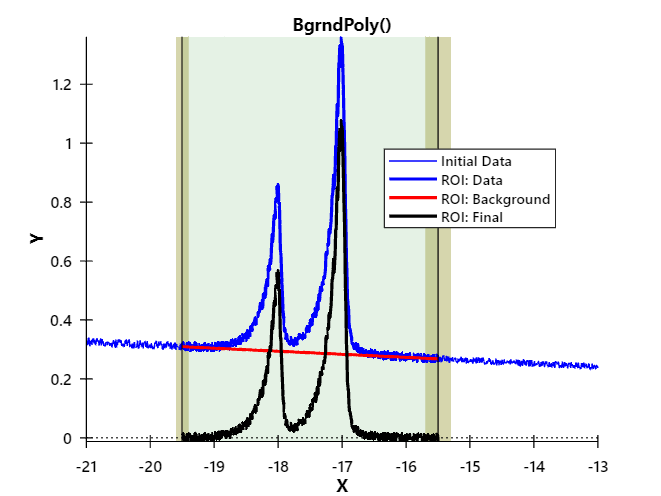

% 1 - Defining the input parameters
polyOrder   = 1;                % scalar, positive integer of the Polynomial Order.
% 2 - Extracting best background
[roi_xdat_01, roi_ydat_01, roi_bgrnd_01] = BgrndPoly(xdat_01, ydat_01, polyOrder, lhsVal, rhsVal, lhsWin, rhsWin, 1);

## (2) Shirley background

help BgrndShirley;

  [roi_xdat, roi_ydat, roi_bgrnd] = BgrndShirley(xdat, ydat, lhsVal, rhsVal, lhsWin, rhsWin, plot_result)
    Function that determines the best fit to the background of PES (or 1D) 
    data using a Shirley function. The output is a column vector containing
    the background intensity, and the new domain and intensity of the data 
    within the defined region of interest.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES)
    -   ydat:           N×1 column vector of the intensity range (intensity for PES)
    -   lhsVal:         scalar of the LHS x-axis start position of the ROI.
    -   rhsVal:         scalar of the RHS x-axis end position of the ROI.
    -   lhsWin:         scalar of the LHS window size around the start position.
    -   rhsWin:         scalar of the RHS window size around the end position.
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
 

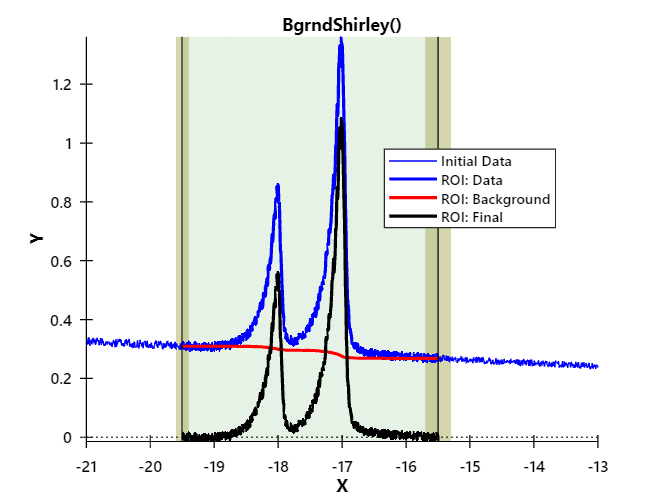

% 1 - Defining the input parameters
% 2 - Extracting best background
[roi_xdat_01, roi_ydat_01, roi_bgrnd_01] = BgrndShirley(xdat_01, ydat_01, lhsVal, rhsVal, lhsWin, rhsWin, 1);

## (3) Blended Shirley and Linear Backgrounds

help BgrndShirleyOffset;

  [roi_xdat, roi_ydat, roi_bgrnd] = BgrndShirleyOffset(xdat, ydat, lambda, delta, lhsVal, rhsVal, lhsWin, rhsWin, plot_result)
    Function that determines the best fit to the background of PES (or 1D) data
    using an Offset Shirley function. This is a blend between a Shirley and
    linear background and is defined by the parameters lambda and delta.
    The output is a column vector containing the background intensity, and
    the new domain and intensity of the data within the defined region of interest.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES)
    -   ydat:           N×1 column vector of the intensity range (intensity for PES)
    -   lambda:         scalar for mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
    -   delta:          scalar for the Shirley curve offset in binding energy.
    -   lhsVal:         scalar of the LHS x-axis start position of the ROI.


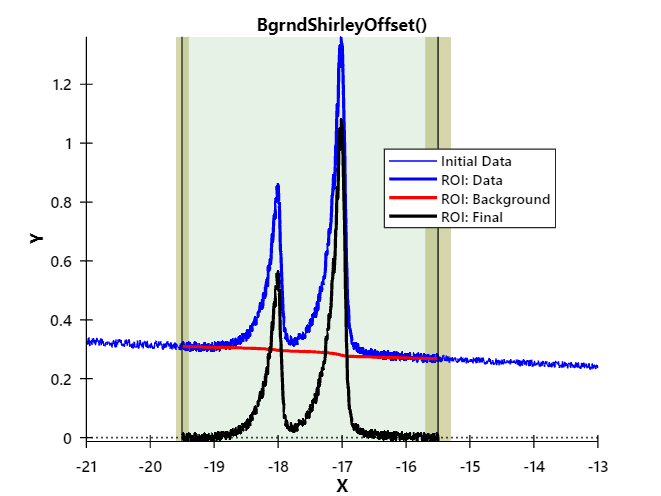

% 1 - Defining the input parameters
lambda      = 0.5;             % scalar for mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
delta       = 0.0;              % scalar for the Shirley curve offset in binding energy.
% 2 - Extracting best background
[roi_xdat_01, roi_ydat_01, roi_bgrnd_01] = BgrndShirleyOffset(xdat_01, ydat_01, lambda, delta, lhsVal, rhsVal, lhsWin, rhsWin, 1);

# **Near Fermi-Edge background determination**

% Defining the window over which to determine the background
lhsVal      = -0.5;             % scalar of the LHS x-axis start position of the ROI.
rhsVal      = 0.5;              % scalar of the RHS x-axis end position of the ROI.
lhsWin      = 0.05;              % scalar of the LHS window size around the start position.
rhsWin      = 0.05;              % scalar of the RHS window size around the end position.

## (1) Fermi-Dirac Distribution (FDD) multiplied by linear function background

% (A) - Creating artificial lineshape
xdat_02     = linspace(-0.8, 0.8, 1e3);
ydat_021    = FDDGpL(xdat_02, 0, 12, 0.1, -2, 1.5, 0.00);
ydat_022    = Gauss(xdat_02, 0, 2.5, 0.25);
ydat_02     = ydat_021 + ydat_022;
% (B) - Add artificial background and noise
ydat_02     = ydat_02 + 0.1;
ydat_02     = ydat_02 + 0.1*rand(length(ydat_02), 1);
% (C) - Extracting help
help BgrndStepFDDGpL;

  [roi_xdat, roi_ydat, roi_bgrnd] = BgrndStepFDDGpL(xdat, ydat, fdd_ef, fdd_T, fdd_fwhm, lhsVal, rhsVal, lhsWin, rhsWin, plot_result)
    Function that determines the best fit to the background of PES (or 1D) 
    data using a single FDD step. The output is a column vector containing
    the background intensity, and the new domain and intensity of the data 
    within the defined region of interest. Here, a linear background is
    MULTIPLIED to the FDD function, so the background is fitted to the
    the gradient, intercept and constant.
    
    REQ. FUNCTIONS: none
    
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES)
    -   ydat:           N×1 column vector of the intensity range (intensity for PES)
    -   fdd_ef:         scalar of the Fermi-level position (eV).
    -   fdd_T:          scalar of the temperature (K).
    -   fdd_fwhm:       scalar of the full-width at half-maximum (FWHM) of the Gaussian broadening ter

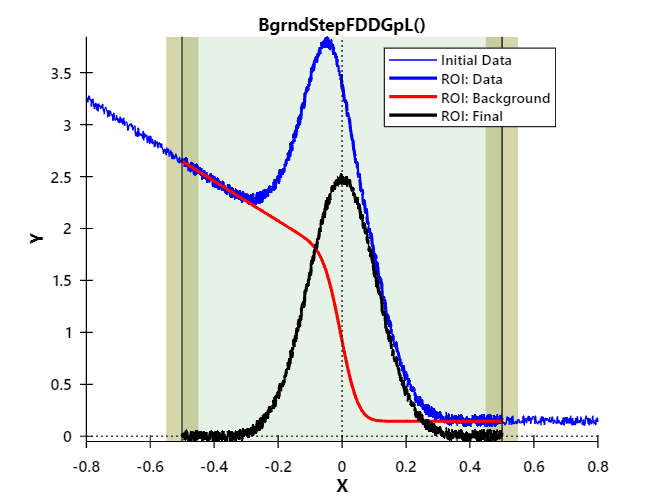

% (D) - Defining the input parameters
fdd_ef      = 0.;
fdd_T       = 12;
fdd_fwhm    = 0.1;
% (E) - Extracting best background
[roi_xdat_02, roi_ydat_02, roi_bgrnd_02] = BgrndStepFDDGpL(xdat_02, ydat_02, fdd_ef, fdd_T, fdd_fwhm, lhsVal, rhsVal, lhsWin, rhsWin, 1);

## (2) Fermi-Dirac Distribution (FDD) summed by linear function background

% (A) - Creating artificial lineshape
xdat_02     = linspace(-0.8, 0.8, 1e3);
ydat_021    = FDDGsL(xdat_02, 0, 12, 0.1, -2, 1.5, 0.00);
ydat_022    = Gauss(xdat_02, 0, 2.5, 0.25);
ydat_02     = ydat_021 + ydat_022;
% (B) - Add artificial background and noise
ydat_02     = ydat_02 + 0.1;
ydat_02     = ydat_02 + 0.1*rand(length(ydat_02), 1);
% (C) - Extracting help
help BgrndStepFDDGsL;

  [roi_xdat, roi_ydat, roi_bgrnd] = BgrndStepFDDGsL(xdat, ydat, fdd_ef, fdd_T, fdd_fwhm, lhsVal, rhsVal, lhsWin, rhsWin, plot_result)
    Function that determines the best fit to the background of PES (or 1D) 
    data using a single FDD step. The output is a column vector containing
    the background intensity, and the new domain and intensity of the data 
    within the defined region of interest. Here, a linear background is
    SUMMED to the FDD function, so the background is fitted to the
    the gradient, intercept and constant.
    
    REQ. FUNCTIONS: none
    
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES)
    -   ydat:           N×1 column vector of the intensity range (intensity for PES)
    -   fdd_ef:         scalar of the Fermi-level position (eV).
    -   fdd_T:          scalar of the temperature (K).
    -   fdd_fwhm:       scalar of the full-width at half-maximum (FWHM) of the Gaussian broadening term (e

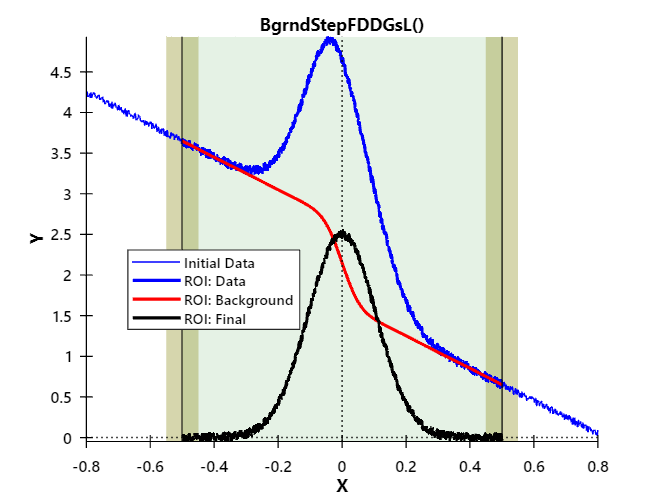

% (D) - Defining the input parameters
fdd_ef      = 0.;
fdd_T       = 12;
fdd_fwhm    = 0.1;
% (E) - Extracting best background
[roi_xdat_02, roi_ydat_02, roi_bgrnd_02] = BgrndStepFDDGsL(xdat_02, ydat_02, fdd_ef, fdd_T, fdd_fwhm, lhsVal, rhsVal, lhsWin, rhsWin, 1);